**Задание: Вы синтезировали регулятор контура скорости в п.3. Как изменится настройка системы управления, если датчик скорости будет выдавать значение скорости в угл. мин./с и будет обладать инерционностью в виде апериодического звена с постоянной времени Tsens = 0.8*To. Привести формулы для вычисления новых коэффициентов регулятора и графики переходных процессов.**

load("data.mat")

syms ia ua Md wd ea  % ток, напряжение, момент, скорость, противо-ЭДС
syms L R J Ce  % индуктивность, сопротивление, момент инерции, коэффициент противо-ЭДС
syms dia dwd  % производные по току и по скорости

eq(1) = ua - ea == L*dia + R*ia;  % уравнение для электрической части
eq(2) = J*dwd == Md;  % уравнение для механической части
eq(3) = Md == Ce*ia;
eq(4) = ea == Ce*wd;

S = solve(eq,[dia dwd Md ea]);
disp(collect(S.dia,[ia wd ua]))

$$\left(-\frac{R}{L}\right)\,\mathrm{ia}+\left(-\frac{\mathrm{Ce}}{L}\right)\,\mathrm{wd}+\frac{\mathrm{ua}}{L}$$

disp(collect(S.dwd,[ia wd ua]))

$$\frac{\mathrm{Ce}}{J}\,\mathrm{ia}$$

A = [-R/L -Ce/L;
     Ce/J 0];
B = [1/L; 0];
C = [0 1];
D = 0;

syms s
Wwa = C*(s*eye(2)-A)^-1*B+D;
disp(collect(Wwa))

$$\frac{\mathrm{Ce}}{\left(J\,L\right)\,s^{2}+\left(J\,R\right)\,s+{\mathrm{Ce}}^{2}}$$

syms T1 T2 Kob
Wsmp = Kob/((T1*s+1)*(T2*s+1))

$$Wsmp = \frac{\mathrm{Kob}}{\left(T_{1}\,s+1\right)\,\left(T_{2}\,s+1\right)}$$

disp(collect(expand(Wsmp),s))

$$\frac{\mathrm{Kob}}{\left(T_{1}\,T_{2}\right)\,s^{2}+\left(T_{1}+T_{2}\right)\,s+1}$$

eqn(1) = T1*T2 == J*L/Ce^2;
eqn(2) = T1+T2 == J*R/Ce^2;
S2 = solve(eqn,[T1 T2]);
S2.T1

$$ans = \left(\begin{array}{c} \frac{J\,R}{{\mathrm{Ce}}^{2}}-\frac{\sqrt{-J\,\left(4\,{\mathrm{Ce}}^{2}\,L-J\,R^{2}\right)}+J\,R}{2\,{\mathrm{Ce}}^{2}}\\ \frac{\sqrt{-J\,\left(4\,{\mathrm{Ce}}^{2}\,L-J\,R^{2}\right)}-J\,R}{2\,{\mathrm{Ce}}^{2}}+\frac{J\,R}{{\mathrm{Ce}}^{2}} \end{array}\right)$$

S2.T2

$$ans = \left(\begin{array}{c} \frac{\sqrt{-J\,\left(4\,{\mathrm{Ce}}^{2}\,L-J\,R^{2}\right)}+J\,R}{2\,{\mathrm{Ce}}^{2}}\\ -\frac{\sqrt{-J\,\left(4\,{\mathrm{Ce}}^{2}\,L-J\,R^{2}\right)}-J\,R}{2\,{\mathrm{Ce}}^{2}} \end{array}\right)$$

ob.T2 = ((-ob.J*(4*ob.L*ob.Ce^2 - ob.J*ob.R^2))^(1/2) + ob.J*ob.R)/(2*ob.Ce^2);
ob.T1 = -((-ob.J*(4*ob.L*ob.Ce^2 - ob.J*ob.R^2))^(1/2) - ob.J*ob.R)/(2*ob.Ce^2);
disp(ob.T1)

    0.0026



disp(ob.T2)

  245.9089



ob.Kob = ob.kdw/ob.Ce;

Tmdl = 1;

spl.Tu = ob.T1;
To = 0.1*spl.Tu;

Tsen = 0.8*To;
ksen = 60;

spl.Kp1 = ob.T2/(ksen*ob.Kob*2*spl.Tu);
spl.Ki1 = 1/(ksen*ob.Kob*2*spl.Tu);
spl.Kp2_an = 1;
spl.Kd2_an = Tsen;
spl.Kp2_dg = 1;
spl.Kd2_dg = 1/(exp(To/Tsen)-1);

warning off
SimNew = sim('new_assignment_1.slx','ReturnWorkspaceOutputs', 'on');
warning on

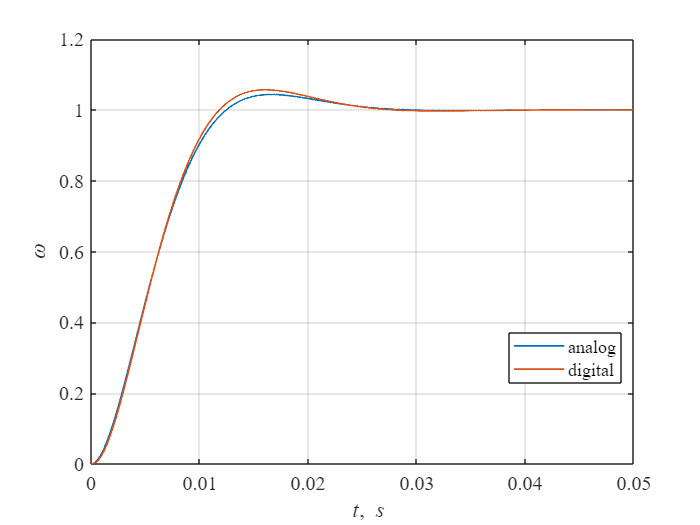

t = SimNew.out(:,1);
wa=SimNew.out(:,2);
wd=SimNew.out(:,3);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wa,'LineWidth',1)
hold on
grid on
plot(t,wd,'LineWidth',1)
xlabel('\it t\rm,\it s')
ylabel('\omega')
legend('analog','digital','Location','best')
xlim([0 0.05])

Время переходного процесса tp1 (5% зона)

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp1 для 5% зоны: 4.0*Tu 


Время переходного процесса tp2 (5% зона)

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp2 для 5% зоны: 6.8*Tu 


Перерегулирование

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 5.7%


**в) Аппроксимация апериодическим звеном**

Tmdl = 0.1;

for i = 1:20
    spl.Tz = 0.9/(21-i)*To;  % диапазон изменения Tz
    Tzap(i) = spl.Tz;
    warning off
    SimNew = sim('lab5p4b_simm.slx','ReturnWorkspaceOutputs', 'on');
    warning on

    t = SimNew.w(:,1);
    wa = SimNew.w(:,3);
    wd = SimNew.w(:,4);
    f(i) = trapz(t,abs(wd-wa));  % интеграл разности между переходными функциями, рассчитанный по методу трапеции
end

Теперь строим график и ищем минимум функционала

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(Tzap/To,f,'LineWidth', 1)
hold on
grid on
xlabel('\it T_{zap}/T_o')
ylabel('\it f')
xlim([0; 0.5])

**г) Синтез цифрового регулятора скорости "методом переоборудования"**

To = 0.1*T1

Tmdl = 0.01;

To = 0.1*ob.T1;
spl.Tz = 0.45*To;
spl.Tur = 0.5*To;
spl.Tu = spl.Tur+spl.Tz;

spl.Kpa1 = ob.T2/(8*ob.Kob*spl.Tu*spl.Tu);
spl.Kia1 = 1/(8*ob.Kob*spl.Tu*spl.Tu);
spl.Kpa2 = 4*spl.Tu;
spl.Kia2 = 1;
spl.Kpa3 = 1;
spl.Kda3 = ob.T1;

spl.Kpd1 = ob.T2/(8*ob.Kob*spl.Tu*spl.Tu);
spl.Kid1 = 1/(8*ob.Kob*spl.Tu*spl.Tu);
spl.Kpd2 = 4*spl.Tu;
spl.Kid2 = 1;
spl.Kpd3 = 1;
spl.Kdd3 = 1/(exp(To/ob.T1)-1);

warning off
SimNew = sim('lab5p4b_simm.slx','ReturnWorkspaceOutputs', 'on');
warning on

t = SimNew.w(:,1);
wref = SimNew.w(:,2);
wa=SimNew.w(:,3);
wd=SimNew.w(:,4);
wdg=SimNew.w(:,5);

h = figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'LineWidth',1)
hold on
grid on
plot(t,wa,'LineWidth',1)
plot(t,wd,'LineWidth',1)
plot(t,wdg,'LineWidth',1)
xlim([0 Tmdl])
xlabel('\it t\rm,\it s')
ylabel('\omega')
legend('задание по скорости','скорость ДПТ с аналоговым регулятором','скорость ДПТ с дискретным регулятором','дискретный сигнал','Location','best')
xlim([0 0.006])

Время переходного процесса tp1 (5% зона)

t0 = t(1);
y = wd;
y0 = wd(1);
yss = wd(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn = t(ind);
ttr5 = tn(1)-t0;
fprintf('Время переходного процесса tp1 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Время переходного процесса tp2 (5% зона)

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn = t(ind);
ttr5 = tn(end)-t0;
fprintf('Время переходного процесса tp2 для 5%% зоны: %.1f*Tu \n',ttr5/spl.Tu)

Перерегулирование

dy = abs(max(y)-yss)/abs(yss-y0);
fprintf('Перерегулирование: %.1f%%\n',dy*100)